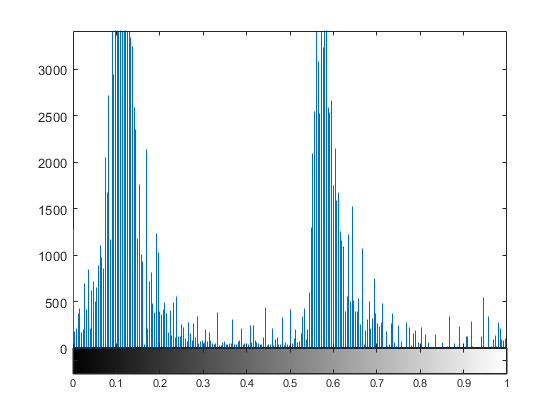

histDetes =         1276
         180
         208
         376
         429
         170
         196
         700
         411
         846


a =         1276
         180
         208
         376
         429
         170
         196
         700
         411
         846


b =          0
    0.0039
    0.0078
    0.0118
    0.0157
    0.0196
    0.0235
    0.0275
    0.0314
    0.0353


im = imread("images\starfish_5.jpg");
im = rgb2hsv(im);
[c1,c2,c3] = imsplit(im);


suspect = 1;

% Create hist
imhist(c1);


% Get hist stats
imMAX = maxk(im, 2);
imMAX1 = imMAX(1)

imMAX1 = 0.6167

% imMAX2 = imMAX(2)
imSTD = std2(im)

imSTD = 0.3012

imMEAN = mean2(im)

imMEAN = 0.4492

meanPlusSTD = imMEAN + imSTD

meanPlusSTD = 0.7504

meanMinusSTD = imMEAN - imSTD

meanMinusSTD = 0.1480


% See if max is within mean +/- std
suspect =  (imMAX1 < meanPlusSTD && imMAX1 > meanMinusSTD)

suspect = logical
   1



if (suspect)
%     Split at mean and repeat
    halfMean = imMEAN / 2
    half1 = im < halfMean;
    half2 = im > halfMean;

% % % % % % %     
% %     
% Get hist stats
imMAX = maxk(half1, 2);
imMAX1 = imMAX(1)
% imMAX2 = imMAX(2)
imSTD = std2(half1)
imMEAN = mean2(half1)
meanPlusSTD = imMEAN + imSTD
meanMinusSTD = imMEAN - imSTD

% See if max is within mean +/- std
suspect =  (imMAX1 < meanPlusSTD && imMAX1 > meanMinusSTD)

end

halfMean = 0.2246

imMAX1 = logical
   1


imSTD = 0.4836

imMEAN = 0.3730

meanPlusSTD = 0.8566

meanMinusSTD = -0.1106

suspect = logical
   0
